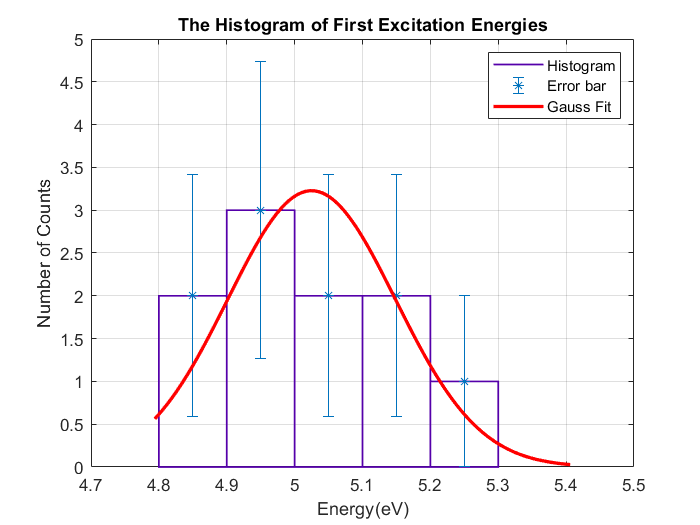


% Force all inputs to be column vectors
E = E(:);

% Prepare figure
clf;
hold on;
LegHandles = []; LegText = {};


% --- Plot data originally in dataset "E data"
[CdfF,CdfX] = ecdf(E,'Function','cdf');  % compute empirical cdf
BinInfo.rule = 5;
BinInfo.width = 0.1;
BinInfo.placementRule = 1;
[~,BinEdge] = internal.stats.histbins(E,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'E data';

% Create grid where function will be computed
XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XGrid = linspace(XLim(1),XLim(2),100);

%creating error bars

e=[2 3 2 2 1];
b= 4.85:0.1:5.25;
err=sqrt(elements);

errorbar(b,e, err,'*');


% --- Create fit "fit 2"

% Fit this distribution to get parameter values
% To use parameter estimates from the original fit:
%     pd1 = ProbDistUnivParam('normal',[ 5.025, 0.1235808327461])
pd1 = fitdist(E, 'normal');
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 2';

% Adjust figure
box on;
hold off;

% Create legend from accumulated handles and labels
hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

grid on
title('The Histogram of First Excitation Energies')
xlabel('Energy(eV)')
ylabel('Number of Counts')

legend({'Histogram','Error bar','Gauss Fit'})


%Mean:            5.025
%Variance:        0.0152722
%R-square: 0.7872
